# Assignment_01

## 1 Simple filters

### 1.1 Impulse responses, transfer functions

-  Find the poles and zeros of the filters with order 3 and 5 by calculating the roots of the corresponding polynomial with the `root` function

% Declare transfer function variable z
z = tf('z');

% Transfer function of 3rd and 5th order running sum filters IR, H_RS3 and H_RS5
H_RS3 = (z^3+z^2+z^1+z^0)/(z^3);
H_RS5 = (z^5+z^4+z^3+z^2+z^1+z^0)/(z^5);

% Extract numerator and denominator polynomials from transfer functions
[num_RS3,den_RS3] = tfdata(H_RS3,'v');
[num_RS5,den_RS5] = tfdata(H_RS5,'v');

% Determine poles and zeros by taking the roots of both polynomials
poles_RS3 = roots(den_RS3);
zeros_RS3 = roots(num_RS3);
poles_RS5 = roots(den_RS5);
zeros_RS5 = roots(num_RS5);

- Plot the poles, the zeros and the frequency response of the filters using `zplane` and `freqz`

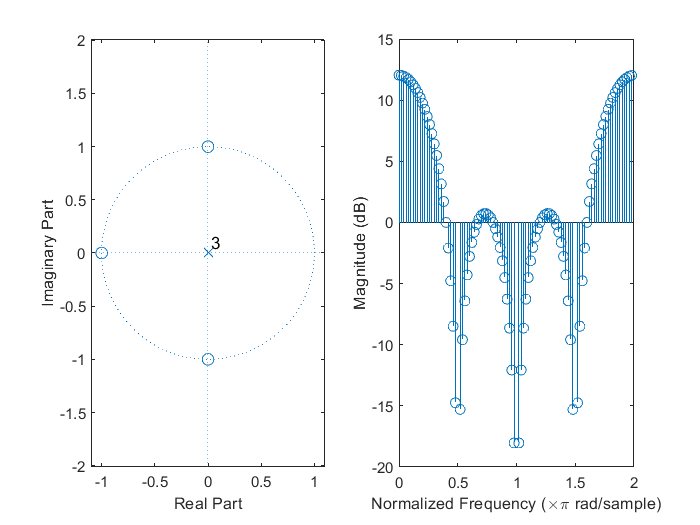

% Compute the frequency responses of both filter's IR
[h_RS3,w_RS3] = freqz(num_RS3,den_RS3,100,"whole"); 
[h_RS5,w_RS5] = freqz(num_RS5,den_RS5,100,"whole"); 

% Plot of 3rd order running sum filter IR's poles and zeros in z-plane and frequency response
figure("Name", "z-plane pole-zero and frequency response plot for 3rd order running sum filter IR");
subplot(1,2,1)
zplane(zeros_RS3,poles_RS3)
subplot(1,2,2)
stem(w_RS3/pi,mag2db(abs(h_RS3)))
ax = gca;
ax.XLim = [0 2]; 
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

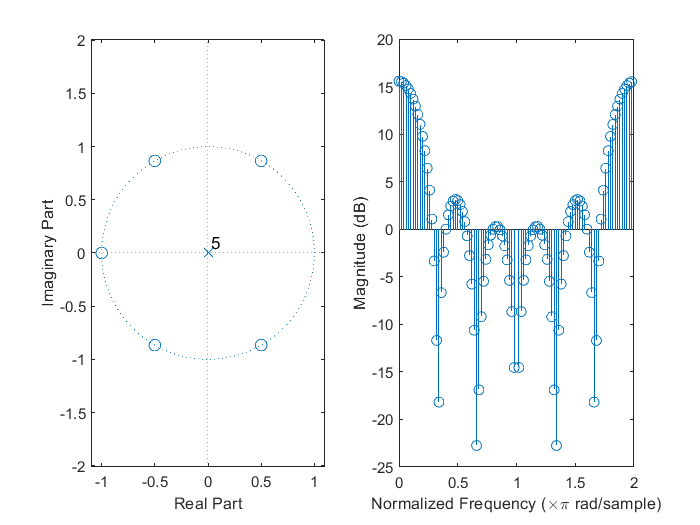

% Plot of 5th order running sum filter IR's poles and zeros in z-plane and frequency response
figure("Name", "z-plane pole-zero and frequency response plot for 5th order running sum filter IR");
subplot(1,2,1)
zplane(zeros_RS5,poles_RS5)
subplot(1,2,2)
stem(w_RS5/pi,mag2db(abs(h_RS5)))
ax = gca;
ax.XLim = [0 2]; 
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

- What happens to the frequency response when considering a moving average rather than a running sum? Recall, that the impulse response of the moving average $h_{MA} \left(n\right)$ is the impulse response of the running sum normalized by the length of the impulse response $N_0 =N+1$:


$$h_{MA} \left(n\right)=\frac{1}{N_0 }\cdot h_{RS}$$


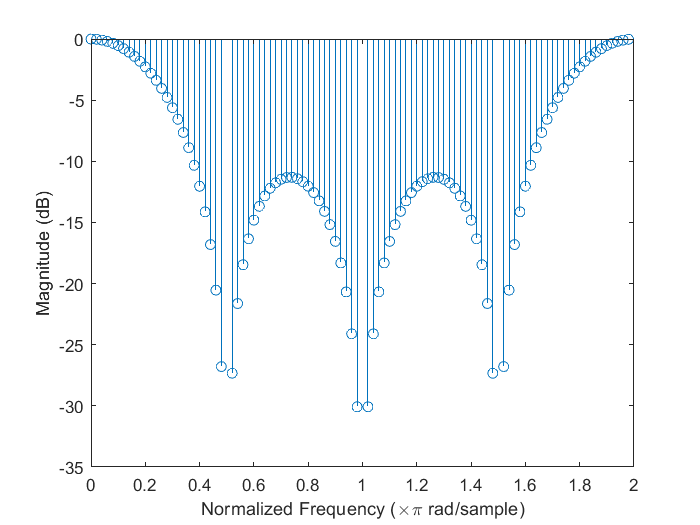

% Compute the moving average IR according to the formula above
h_MA3 = 1/4 * h_RS3;
h_MA5 = 1/6 * h_RS5; 

% Plot the frequency response of the 3rd and 5th order moving average
figure("Name","3rd order moving average frequency response")
stem(w_RS3/pi,mag2db(abs(h_MA3)))
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')
figure("Name","5th order moving average frequency response")

stem(w_RS5/pi,mag2db(abs(h_MA5)))
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

- Some frequencies are heavily suppressed (attenuated) in these filters. Is there a simple way to enhance (that means to amplify) these frequencies rather than to attenuate them? 

Yes - place LHP poles at the wanted frequencies to amplify the signal. 

- Design a filter that blocks the normalized frequency of 0.1 by placing 4 zeros in the z-plane. Make sure the filter returns real-values outputs when fed with real-valued inputs by placing complex-conjugate pairs of poles and zeros.

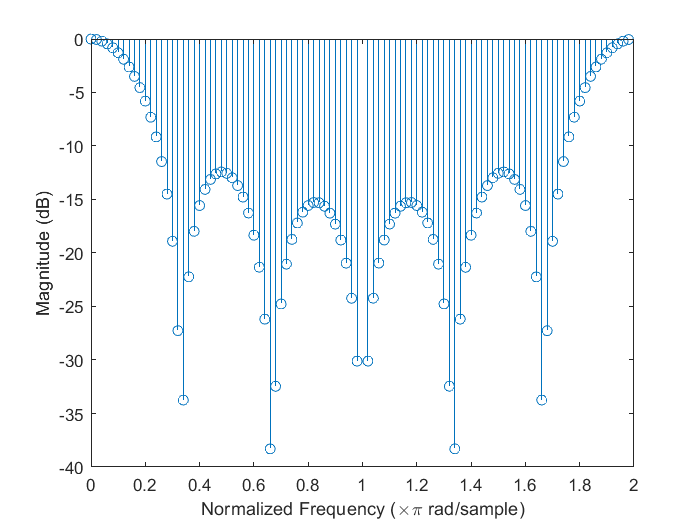

a = sqrt(0.1/2); 

% Zeros of filter transfer function
Z = [-0.1 -0.1 -a+a*1i a-a*1i]; 

% Filter transfer function
H = zpk(Z,1,1)

H =
 
  (s+0.1)^2 (s+(0.2236-0.2236i)) (s-(0.2236-0.2236i))
  ---------------------------------------------------
                         (s-1)
 
Continuous-time zero/pole/gain model.



- Add to the previous filter 4 poles lying on a circle with a radius $R<1$ (you chose $R$) at angles identical to the angles of the zeros. How does the frequency response change when you increase $R$ and when $R$ approaches 1? 

### 1.2 The power of poles and zeros